X = zeros(128*128*128,1);
Y = zeros(128*128*128,1);
Z = zeros(128*128*128,1);
data = zeros(128*128*128,1);
i = 0

i = 0

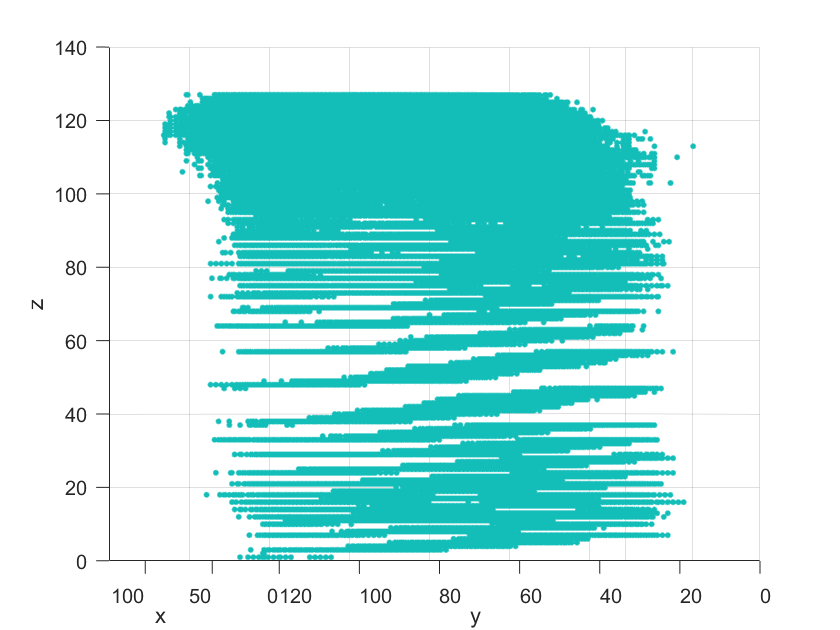

for z = 1:128
    for y = 1:128
        for x = 1:128
            if output1(z, y, x) > 0.30
                i = i+1;
                X(i) = x;
                Y(i) = y;
                Z(i) = z;
                data(i) = ct1(z,y,x);
            end
        end
    end
end
S = repmat([70,50,20],numel(X),1);
C = repmat([1,2,3],numel(X),1);
s = S(:);
c = C(:);
scatter3(X(1:i), Y(1:i), Z(i:-1:1), s(1:i), c(1:i), "Marker",".");
xlabel('x');
ylabel('y');
zlabel('z');
alpha(0.5);
hold off;

% colorbar
